% Date- 26-08-2025
% Lab- 4
% Q-1

fun = @(x) exp(-x.^2).*log(x).^2;
I = integral(fun,0,Inf)

I = 1.9475


fun1= @(x) x.^5.*exp(-x).*sin(x);

fun1 =     @(x)x.^5.*exp(-x).*sin(x)


I1 = integral(fun1,0,Inf)

I1 = -15.0000

% Q-2
fun2 = @(x) x.^3./(exp(x)-1);
I2 = integral(fun2,0,Inf)

I2 = 6.4939

% Q-3
fun = @(x) exp(sin(7*x));
T = trapezoid(fun, 0, 2,40)

T = 2.6623

I = integral(fun,0,2)

I = 2.6632

error = abs(I-T)

error = 9.1685e-04



n = 40*2.^(0:5);
err = zeros(size(n));
for k = 1:length(n)
    T = trapezoid(fun,0,2,n(k));
    err(k) = abs(I - T);
end


loglog(n,err,'.-')

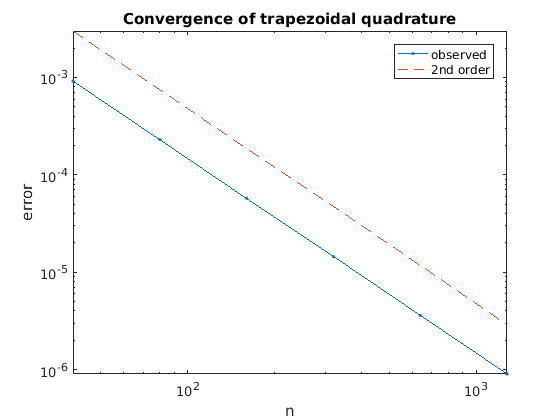

hold on, loglog(n,3e-3*(n/n(1)).^(-2),'--')
xlabel('n'), ylabel('error'), axis tight
title('Convergence of trapezoidal quadrature')
legend('observed','2nd order')

function I = trapezoid(f, a, b, n)
    h = (b-a)/n;
    x = a+h*(0:n);
    y = f(x);
    I = h*( sum(y(2:n))+ 0.5*(y(1)+y(n+1)));
end